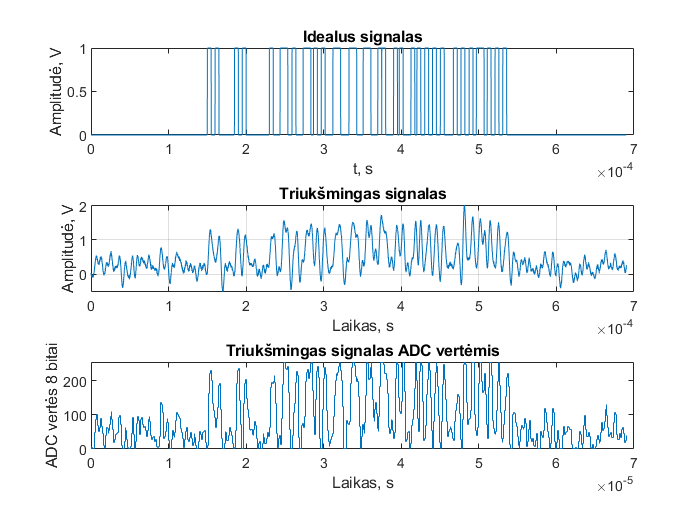

fdiskret = 10E6;
tdiskret = 1/fdiskret;

tprescaler = 10;

idealOne = [ones(1, round(0.5E-6/tdiskret*tprescaler)), zeros(1, round(0.5E-6/tdiskret*tprescaler))];
idealZero = [zeros(1, round(0.5E-6/tdiskret*tprescaler)), ones(1, round(0.5E-6/tdiskret*tprescaler))];

dataSend = "1011011101010101010111100001111";
[idealSignal, noisySignal, discretizedSignal, ADCsignal, ADCpreambule] = GenerateSignal(dataSend, 1);

%{
[idealSignal2, noisySignal2, discretizedSignal2, ADCsignal2, ADCpreambule2] = GenerateSignal(dataSend, 1);

susceilintas = [zeros(1, 500), noisySignal2];
susceilintas = susceilintas(1:length(noisySignal));
suPersidengimuSignalas = noisySignal + susceilintas;
suPersidengimuSignalas = suPersidengimuSignalas(1:10:length(suPersidengimuSignalas));
%}
N = length(idealSignal);
n = 0:N-1;
t = 0:1/fdiskret:1/fdiskret*(N-1);

subplot(3, 1, 1)
plot(t, idealSignal)
xlabel('t, s')
ylabel('Amplitudė, V')
title('Idealus signalas')

%Filtro š

subplot(3, 1, 2)
plot(t, noisySignal)
ylabel('Amplitudė, V')
xlabel('Laikas, s')
title('Triukšmingas signalas')
grid on

subplot(3, 1, 3)
N = length(ADCsignal);
n = 0:N-1;
t = 0:1/fdiskret:1/fdiskret*(N-1);
stairs(t, ADCsignal)
ylabel('ADC vertės 8 bitai')
xlabel('Laikas, s')
title('Triukšmingas signalas ADC vertėmis')
ylim([0, 255])

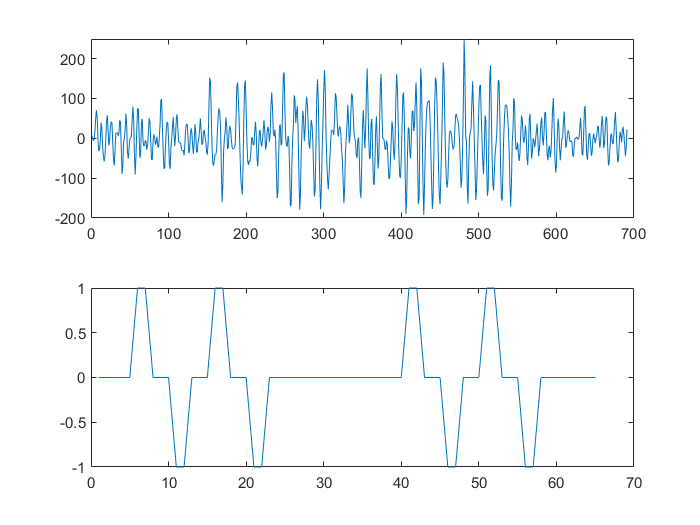

pastumimasN = 2;
idealPreambule = [zeros(1, 5), ones(1, round(0.5E-6/tdiskret)), zeros(1, round(0.5E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret)), zeros(1, round(2E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret)), zeros(1, round(0.5E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret)), zeros(1, 10)];
pastumtaPreambule = [zeros(1, pastumimasN), idealPreambule(1:length(idealPreambule)-pastumimasN)];
diferencijuotaPreambule = idealPreambule - pastumtaPreambule;

pastumtas = [zeros(1, pastumimasN), ADCsignal(1:length(ADCsignal)-pastumimasN)];
diferencijuotasPilnas = ADCsignal - pastumtas;
figure
subplot(2, 1, 1)
plot(diferencijuotasPilnas)
subplot(2, 1, 2)
plot(diferencijuotaPreambule)

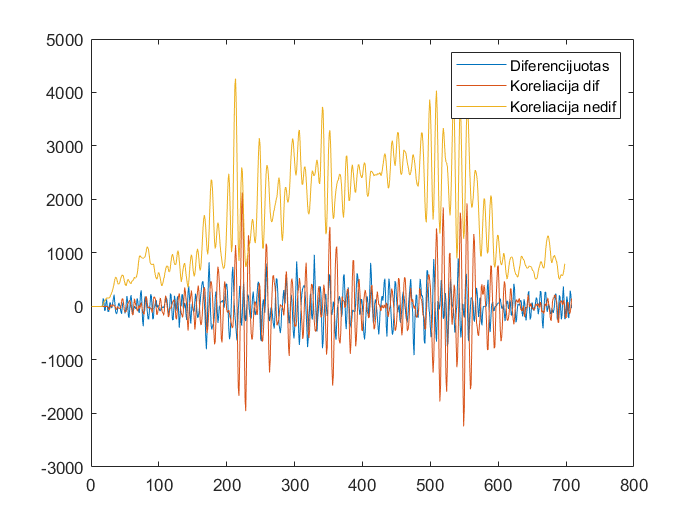


pastumimasN = 2;
idealPreambule = [zeros(1, 5), ones(1, round(0.5E-6/tdiskret)), zeros(1, round(0.5E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret)), zeros(1, round(2E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret)), zeros(1, round(0.5E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret)), zeros(1, 10)];
pastumtaPreambule = [zeros(1, pastumimasN), idealPreambule(1:length(idealPreambule)-pastumimasN)];
diferencijuotaPreambule = idealPreambule - pastumtaPreambule;
[idealSignal, noisySignal, discretizedSignal, ADCsignal, ADCpreambule] = GenerateSignal(dataSend, 1);
            
ADCsignal2 = [zeros(1, 10), ADCsignal];
pastumtas = [zeros(1, pastumimasN), ADCsignal2(1:length(ADCsignal2)-pastumimasN)];
diferencijuotasPilnas = ADCsignal2 - pastumtas;
y = GenerateConv(diferencijuotasPilnas, diferencijuotaPreambule); %diferencijuotas
yy = GenerateConv(ADCsignal, idealPreambule); %diferencijuotas
figure
plot(diferencijuotasPilnas*4)
hold on
plot(y)
plot(yy)
legend("Diferencijuotas", "Koreliacija dif", "Koreliacija nedif")
hold off

[a, b] = max(y)

a = 2132

b = 223

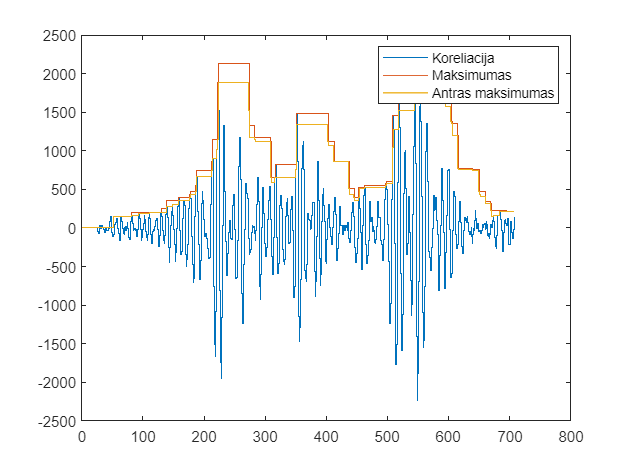

max1 = [zeros(1, 50)];
max2 = [zeros(1, 50)];
for i = 1:length(y)-50
     [maksimumai, indeksai] = maxk(y(i:i+50),2);
     max1 = [max1, maksimumai(1)];
     max2 = [max2, maksimumai(2)];
end

stairs(y)
hold on
stairs(max1)
stairs(max2)

legend("Koreliacija", "Maksimumas", "Antras maksimumas")
hold off


%{
figure
subplot(2, 1, 1)
plot(susceilintas)
ylabel('Amplitudė, V')
xlabel('Laikas, s')
title('Su persidengimu')
grid on

subplot(2, 1, 2)
plot(suPersidengimuSignalas)
ylabel('Amplitudė, V')
xlabel('Laikas, s')
title('Su persidengimu')
grid on
%}
figure
snr(ADCsignal, discretizedSignal)

ans = 45.0222

clear
%Koreliacijos max priklausomybe nuo amplitudes

amplitude_duom = [];
preambules_max_duom = [];
rms_duom = [];
eng_duom = [];
preambules_max_duom2 = [];
preambules_max1_error_max = [];
preambules_max1_error_min = [];
preambules_max2_error_max = [];
preambules_max2_error_min = [];
temp_preambules_max1_error_max = [];
temp_preambules_max1_error_min = [];
temp_preambules_max2_error_max = [];
temp_preambules_max2_error_min = [];
neteisingi = [];

viso_max_duom = [];
viso_max_duom2 = [];
viso_langas = [];
viso_pastumimas = [];

viso_viso_rms = [];
viso_viso_eng = [];
viso_viso_langas = [];
viso_viso_pastumimas = [];
viso_neteisingi = [];

kiekvienas_max = [];
kiekvienas_max2 = [];

pastumimasN = 2;
fdiskret = 10E6;
tdiskret = 1/fdiskret;
idealPreambule = [zeros(1, 5), ones(1, round(0.5E-6/tdiskret)), zeros(1, round(0.5E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret)), zeros(1, round(2E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret)), zeros(1, round(0.5E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret)), zeros(1, 10)];
pastumtaPreambule = [zeros(1, pastumimasN), idealPreambule(1:length(idealPreambule)-pastumimasN)];
diferencijuotaPreambule = idealPreambule - pastumtaPreambule;

dataSend = "101101";

%Ref itampa 1.4V
langas_temp = [];
pastumimas_temp = [];
%for langas = 70:10:100
for pastumimasN = 2%1:1:10
    langas = 20;
    amplitude_duom = [];
    rms_duom = [];
    eng_duom = [];
    preambules_max_duom = [];
    preambules_max_duom2 = [];
    langas_temp = [];
    neteisingi = 0;
    pastumimas_temp = [];
    temp_preambules_max1_error_max = [];
    temp_preambules_max1_error_min = [];
    temp_preambules_max2_error_max = [];
    temp_preambules_max2_error_min = [];

    for generuojama_amplitude = 0.5:0.05:1.4
        vid_max_y = 0;
        vid_max_y2 = 0;
        vid_rms_y = 0;
        vid_eng_y = 0;
        vienetai = 0;
        
        nepataikyta = 0;
        sugeneruoti_max = zeros(1, 1000);
        sugeneruoti_max2 = zeros(1, 1000);
        
        for i = 1:100
            [idealSignal, noisySignal, discretizedSignal, ADCsignal, ADCpreambule] = GenerateSignal(dataSend, generuojama_amplitude);
            
            ADCsignal2 = [zeros(1, 10), ADCsignal];
            pastumtas = [zeros(1, pastumimasN), ADCsignal2(1:length(ADCsignal2)-pastumimasN)];
            diferencijuotasPilnas = ADCsignal2 - pastumtas;
            y = GenerateConv(diferencijuotasPilnas, diferencijuotaPreambule); %diferencijuotas
            %y = GenerateConv(ADCsignal2, idealPreambule); %Nediferencijuoptas
            [maksimumai, indeksai] = maxk(y,2);
            max_y = maksimumai(1);
            max_y2 = maksimumai(2);
            index_y = indeksai(1);
            sugeneruoti_max(i) = max_y;
            sugeneruoti_max2(i) = max_y2;
            if index_y > 217 && index_y < 227
                vienetai = vienetai + 1;
                vid_max_y = vid_max_y + max_y;
                vid_rms_y = vid_rms_y + rms(ADCsignal(1:langas)); %400 ant 130
                vid_eng_y = vid_eng_y + sum(ADCsignal(1:langas));
                vid_max_y2 = vid_max_y2 + max_y2;

                kiekvienas_max = [kiekvienas_max, max_y];
                kiekvienas_max2 = [kiekvienas_max2, max_y2];
            else
                nepataikyta = nepataikyta + 1;
            end
            
        end
       
        %{
        [a, ~] = max(sugeneruoti_max);
        temp_preambules_max1_error_max = [temp_preambules_max1_error_max, a];
        [a, ~] = min(sugeneruoti_max);
        temp_preambules_max1_error_min = [temp_preambules_max1_error_min, a];
    
        [a, ~] = max(sugeneruoti_max2);
        temp_preambules_max2_error_max = [temp_preambules_max2_error_max, a];
        [a, ~] = min(sugeneruoti_max2);
        temp_preambules_max2_error_min = [temp_preambules_max2_error_min, a];
        %}
        %{
        a = rms(sugeneruoti_max);
        temp_preambules_max1_error_max = [temp_preambules_max1_error_max, a];
        temp_preambules_max1_error_min = [temp_preambules_max1_error_min, a];
        a = rms(sugeneruoti_max2);
        temp_preambules_max2_error_max = [temp_preambules_max2_error_max, a];
        temp_preambules_max2_error_min = [temp_preambules_max2_error_min, a];
        %}
        %{
        a = sum(sugeneruoti_max)/length(sugeneruoti_max)*0.7;
        temp_preambules_max1_error_max = [temp_preambules_max1_error_max, a];
        temp_preambules_max1_error_min = [temp_preambules_max1_error_min, a];
        a = sum(sugeneruoti_max2)/length(sugeneruoti_max2)*0.7;
        temp_preambules_max2_error_max = [temp_preambules_max2_error_max, a];
        temp_preambules_max2_error_min = [temp_preambules_max2_error_min, a];
        %}

        a = prctile(sugeneruoti_max,70);
        temp_preambules_max1_error_max = [temp_preambules_max1_error_max, a];
        temp_preambules_max1_error_min = [temp_preambules_max1_error_min, a];
        a = prctile(sugeneruoti_max2,70);
        temp_preambules_max2_error_max = [temp_preambules_max2_error_max, a];
        temp_preambules_max2_error_min = [temp_preambules_max2_error_min, a];
    
        vid_max_y = vid_max_y / vienetai; %Skaiciuojam vidurki
        vid_rms_y = vid_rms_y / vienetai;
        vid_eng_y = vid_eng_y / vienetai;
        vid_max_y2 = vid_max_y2 / vienetai; %Skaiciuojam vidurki
    
        amplitude_duom = [amplitude_duom, generuojama_amplitude];
        neteisingi = [neteisingi, nepataikyta];
        rms_duom = [rms_duom, vid_rms_y];
        eng_duom = [eng_duom, vid_eng_y];
        preambules_max_duom = [preambules_max_duom, vid_max_y];
        preambules_max_duom2 = [preambules_max_duom2, vid_max_y2];
        langas_temp = [langas_temp, langas];
        pastumimas_temp = [pastumimas_temp, pastumimasN];
    end
    preambules_max1_error_max = [preambules_max1_error_max; temp_preambules_max1_error_max];
    preambules_max1_error_min = [preambules_max1_error_min; temp_preambules_max1_error_min];
    preambules_max2_error_max = [preambules_max2_error_max; temp_preambules_max2_error_max];
    preambules_max2_error_min = [preambules_max2_error_min; temp_preambules_max2_error_min];
    
    viso_neteisingi = [viso_neteisingi; neteisingi];
    viso_viso_langas = [viso_viso_langas; langas_temp];
    viso_viso_pastumimas = [viso_viso_pastumimas; pastumimas_temp];
    viso_viso_rms = [viso_viso_rms; rms_duom];
    viso_viso_eng = [viso_viso_eng; eng_duom];
    viso_max_duom = [viso_max_duom; preambules_max_duom];
    viso_max_duom2 = [viso_max_duom2; preambules_max_duom2];
    viso_langas = [viso_langas, langas];
    viso_pastumimas = [viso_pastumimas, pastumimasN];
end

norm_preambules_max1_error_min = abs(viso_max_duom - preambules_max1_error_min);
norm_preambules_max1_error_max = abs(preambules_max1_error_max - viso_max_duom);
norm_preambules_max2_error_min = abs(viso_max_duom2 - preambules_max2_error_min);
norm_preambules_max2_error_max = abs(preambules_max2_error_max - viso_max_duom2);

viso_skirtumas = viso_max_duom - viso_max_duom2;

skirtumasLowHigh = (preambules_max1_error_min - preambules_max2_error_max) ./ viso_max_duom;

kiekvienas_skirtumas = kiekvienas_max - kiekvienas_max2;
kiekvienas_mean = mean(kiekvienas_skirtumas);
kiekvienas_mean_skirtumas = kiekvienas_skirtumas - kiekvienas_mean;

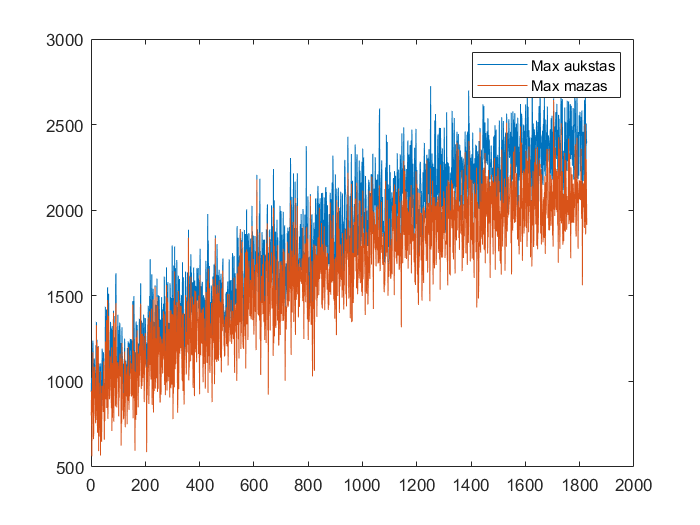

plot(kiekvienas_max)
hold on
plot(kiekvienas_max2)
legend("Max aukstas", "Max mazas")
hold off

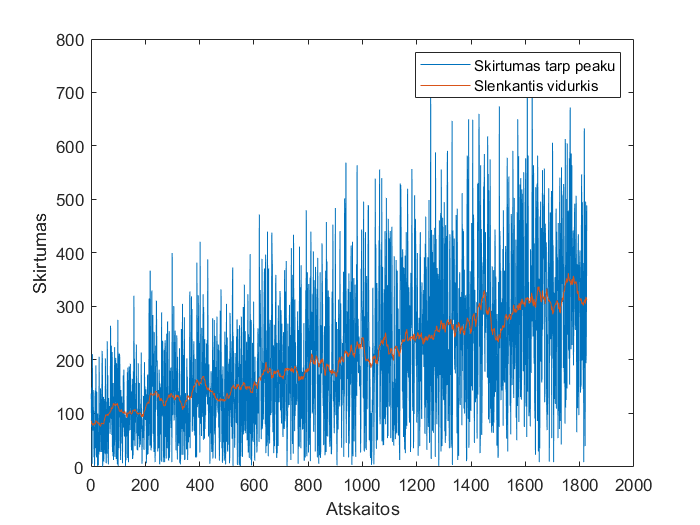


figure
plot(kiekvienas_skirtumas)
hold on
plot(movmean(kiekvienas_skirtumas, 50))
xlabel("Atskaitos")
ylabel("Skirtumas")
legend("Skirtumas tarp peaku", "Slenkantis vidurkis")
hold off

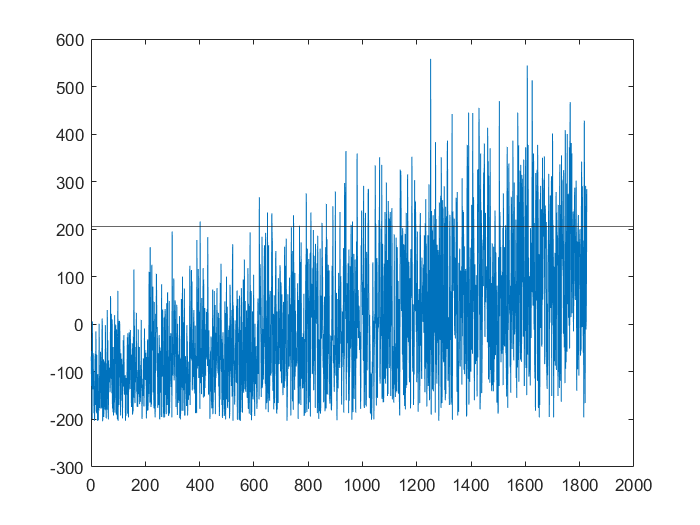

plot(kiekvienas_mean_skirtumas)
hold on
yline(kiekvienas_mean)
hold off

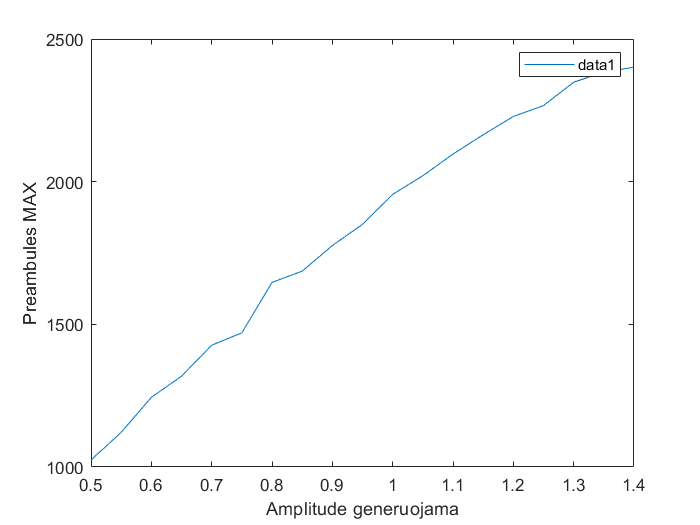


figure
%errorbar(amplitude_duom, preambules_max_duom, preambules_max1_error_min, preambules_max1_error_max)
plot(amplitude_duom, viso_max_duom)
xlabel("Amplitude generuojama")
ylabel("Preambules MAX")
hold on
%errorbar(amplitude_duom, preambules_max_duom2, preambules_max2_error_min, preambules_max2_error_max)
%legend(["Maksimumas 1", "Maksimumas 2"])
legend()
hold off

rodomasIndex = 2;
figure
plot(rms_duom, viso_neteisingi(rodomasIndex, 2:length(viso_neteisingi)))

Index in position 1 exceeds array bounds. Index must not exceed 1.

xlabel("RMS")
ylabel("Neteisingu peaku skaicius is 100")
errorbar(rms_duom, viso_max_duom(rodomasIndex, :), norm_preambules_max1_error_min(rodomasIndex, :), norm_preambules_max1_error_max(rodomasIndex, :))
xlabel("RMS signalo")
ylabel("Preambules MAX")
hold on
errorbar(rms_duom, viso_max_duom2(rodomasIndex, :), norm_preambules_max2_error_min(rodomasIndex, :), norm_preambules_max2_error_max(rodomasIndex, :))
legend(["Maksimumas 1", "Maksimumas 2"])
hold off
figure
plot(rms_duom, skirtumasLowHigh(rodomasIndex, :))
xlabel("RMS signalo")
ylabel("Skirtumas tarp preambules min ir antro peako max")

figure
plot(rms_duom, viso_skirtumas(rodomasIndex, :))
xlabel("RMS signalo")
ylabel("Skirtumas tarp amksimumu")
surf(rms_duom, viso_pastumimas, viso_skirtumas)
%surf(rms_duom, viso_langas , viso_skirtumas)
%surf(eng_duom, viso_langas , viso_skirtumas)
xlabel("RMS");
ylabel("Pastumimas");
zlabel("Skirtumas");
figure
%scatter3(viso_viso_rms(:), viso_viso_langas(:), viso_skirtumas(:), 10, viso_skirtumas(:))
%scatter3(viso_viso_eng(:), viso_viso_langas(:), viso_skirtumas(:), 10, viso_skirtumas(:))
scatter3(viso_viso_pastumimas(:), viso_viso_rms(:), viso_skirtumas(:), 10, viso_skirtumas(:))
xlabel("X RMS")
ylabel("Y Lango ilgis")
zlabel("Z Skirtumas")

clear
%Koreliacijos max priklausomybe nuo amplitudes

amplitude_duom = [];
preambules_max_duom = [];
langas_duom = [];
rms_duom = [];

pastumimasN = 2;
fdiskret = 10E6;
tdiskret = 1/fdiskret;
tprescaler = 1;
idealPreambule = [zeros(1, 5), ones(1, round(0.5E-6/tdiskret*tprescaler)), zeros(1, round(0.5E-6/tdiskret*tprescaler)), ones(1, round(0.5E-6/tdiskret*tprescaler)), zeros(1, round(2E-6/tdiskret*tprescaler)), ones(1, round(0.5E-6/tdiskret*tprescaler)), zeros(1, round(0.5E-6/tdiskret*tprescaler)), ones(1, round(0.5E-6/tdiskret*tprescaler)), zeros(1, 10)];
pastumtaPreambule = [zeros(1, pastumimasN), idealPreambule(1:length(idealPreambule)-pastumimasN)];
diferencijuotaPreambule = idealPreambule - pastumtaPreambule;

dataSend = "101101";

%Ref itampa 1.4V
for generuojama_amplitude = 0:0.1:1.4 %Amplitude X
    vid_max_y = 0;
    vid_rms_y = 0;
    vienetai = 0;
    preambule_max_temp = [];
    langas_duom = [];
    for langas = 1:15
        for i = 1:1 %Vidurkinam
            [idealSignal, noisySignal, discretizedSignal, ADCsignal, ADCpreambule] = GenerateSignal(dataSend, generuojama_amplitude);
            
            ADCsignal2 = [zeros(1, 10), ADCsignal];
            pastumtas = [zeros(1, pastumimasN), ADCsignal2(1:length(ADCsignal2)-pastumimasN)];
            diferencijuotasPilnas = ADCsignal2 - pastumtas;
            y = GenerateConv(diferencijuotasPilnas, diferencijuotaPreambule);
            %stairs(ADCsignal)
            [max_y, index_y] = max(y);
            if index_y > 70 && index_y < 76
                vienetai = vienetai + 1;
                vid_max_y = vid_max_y + max_y;
                vid_rms_y = vid_rms_y + rms(ADCsignal(1:langas));
            end
        end
        vid_max_y = vid_max_y / vienetai; %Skaiciuojam vidurki
        preambule_max_temp = [preambule_max_temp, vid_max_y];
        langas_duom = [langas_duom, langas];
    end
    %langas_duom = [langas_duom; langas_temp];
    
    vid_rms_y = vid_rms_y / vienetai;
    rms_duom = [rms_duom, vid_rms_y];
    amplitude_duom = [amplitude_duom, generuojama_amplitude];
    preambules_max_duom = [preambules_max_duom; preambule_max_temp];
end


%plot(amplitude_duom, preambules_max_duom)
%plot(amplitude_duom, rms_duom)
surf(langas_duom, amplitude_duom, preambules_max_duom)
xlabel("X Lango ilgis")
ylabel("Y Amplitude duom")
zlabel("Z Koreliacinis maksimumas")

clear all
%Koreliacijos max priklausomybe nuo amplitudes

amplitude_duom = [];
preambules_max_duom = [];
langas_duom = [];
rms_duom = [];

pastumimasN = 2;
fdiskret = 10E6;
tdiskret = 1/fdiskret;
tprescaler = 1;
idealPreambule = [zeros(1, 5), ones(1, round(0.5E-6/tdiskret*tprescaler)), zeros(1, round(0.5E-6/tdiskret*tprescaler)), ones(1, round(0.5E-6/tdiskret*tprescaler)), zeros(1, round(2E-6/tdiskret*tprescaler)), ones(1, round(0.5E-6/tdiskret*tprescaler)), zeros(1, round(0.5E-6/tdiskret*tprescaler)), ones(1, round(0.5E-6/tdiskret*tprescaler)), zeros(1, 10)];
pastumtaPreambule = [zeros(1, pastumimasN), idealPreambule(1:length(idealPreambule)-pastumimasN)];
diferencijuotaPreambule = idealPreambule - pastumtaPreambule;

dataSend = "101101";

%Ref itampa 1.4V
for generuojama_amplitude = 0:0.05:1.4 %Amplitude X
    %langas_duom = [];
    for langas = 1:150
        vienetai = 0;
        vid_max_y = 0;
        vid_rms_y = 0;
        for i = 1:1 %Vidurkinam
            [idealSignal, ~, ~, ADCsignal, ADCpreambule] = GenerateSignal(dataSend, generuojama_amplitude);
            
            ADCsignal2 = [zeros(1, 10), ADCsignal];
            pastumtas = [zeros(1, pastumimasN), ADCsignal2(1:length(ADCsignal2)-pastumimasN)];
            diferencijuotasPilnas = ADCsignal2 - pastumtas;
            y = GenerateConv(diferencijuotasPilnas, diferencijuotaPreambule);
            %stairs(ADCsignal)
            [max_y, index_y] = max(y);
            if index_y > 70 && index_y < 76
                if(not(isnan(rms(ADCsignal(1:langas)))))
                    vienetai = vienetai + 1;
                    vid_max_y = vid_max_y + max_y;
                    vid_rms_y = vid_rms_y + rms(ADCsignal(1:langas));
                end
            end
        end
        if(not(vienetai == 0))
            rms_duom = [rms_duom, vid_rms_y/vienetai];
            langas_duom = [langas_duom, langas];
            preambules_max_duom = [preambules_max_duom, vid_max_y/vienetai];
        end
    end
end


figure
scatter3(rms_duom, langas_duom, preambules_max_duom', 10, preambules_max_duom')
xlabel("X RMS")
ylabel("Y Lango ilgis")
zlabel("Z Preambules max")

tri = delaunay(rms_duom,langas_duom);
trimesh(tri, rms_duom, langas_duom, preambules_max_duom);
hold on; plot3(rms_duom,langas_duom,preambules_max_duom,'.')
hold off
xlabel("X RMS")
ylabel("Y Lango ilgis")
zlabel("Z Preambules max")


pastumimasN = 2
ADCsignal = ADCsignal;%suPersidengimuSignalas;

fdiskret = 10E6;
tdiskret = 1/fdiskret;
tprescaler = 1;
idealPreambule = [zeros(1, 5), ones(1, round(0.5E-6/tdiskret*tprescaler)), zeros(1, round(0.5E-6/tdiskret*tprescaler)), ones(1, round(0.5E-6/tdiskret*tprescaler)), zeros(1, round(2E-6/tdiskret*tprescaler)), ones(1, round(0.5E-6/tdiskret*tprescaler)), zeros(1, round(0.5E-6/tdiskret*tprescaler)), ones(1, round(0.5E-6/tdiskret*tprescaler)), zeros(1, 10)];
pastumtaPreambule = [zeros(1, pastumimasN), idealPreambule(1:length(idealPreambule)-pastumimasN)];
diferencijuotaPreambule = idealPreambule - pastumtaPreambule;
ADCsignal2 = [zeros(1, 10), ADCsignal];
pastumtas = [zeros(1, pastumimasN), ADCsignal2(1:length(ADCsignal2)-pastumimasN)];
diferencijuotasPilnas = ADCsignal2 - pastumtas;
y = GenerateConv(diferencijuotasPilnas, diferencijuotaPreambule);

plot(y)
hold on
plot(M)
hold off
[a, b] = max(y)

iOne = [idealOne(1:10:length(idealOne)), zeros(1, pastumimasN*2)];
iZero = [idealZero(1:10:length(idealZero)), zeros(1, pastumimasN*2)];

pOne = [zeros(1, pastumimasN), iOne(1:length(iOne))];
pZero = [zeros(1, pastumimasN), iZero(1:length(iZero))];

pOne = pOne(1:length(iOne));
pZero = pZero(1:length(iZero));

dOne = iOne - pOne;
dZero = iZero - pZero;

dOne = dOne(1:10);
dZero = dZero(1:10);

iOne = idealOne(1:10:length(idealOne));
iZero = idealZero(1:10:length(idealZero));

iZeroZero = [iZero, iZero];
iZeroOne = [iZero, iOne];
iOneZero = [iOne, iZero];
iOneOne = [iOne, iOne];


dOneOne = [0, 0, 0, 0, 0, -1, 0, 0, 0, 0, 1, 0, 0, 0, 0, -1, 0, 0, 0, 0];
dOneZero = [0, 0, 0, 0, 0, -1, 0, 0, 0, 0, 0, 0, 0, 0, 0, 1, 0, 0, 0, 0];
dZeroOne = [0, 0, 0, 0, 0, 1, 0, 0, 0, 0, 0, 0, 0, 0, 0, -1, 0, 0, 0, 0];
dZeroZero = [0, 0, 0, 0, 0, 1, 0, 0, 0, 0, -1, 0, 0, 0, 0, 1, 0, 0, 0, 0];

dOne = [0, 0, 0, 0, 0, -1, -1, 0, 0, 0];
plot(dOne)
dZero = [0, 0, 0, 0, 0, 1, 1, 0, 0, 0];
plot(dZero)
cdOne = GenerateConv(diferencijuotasPilnas, dOne);
cdZero = GenerateConv(diferencijuotasPilnas, dZero);
cOne = GenerateConv(ADCsignal, iOne);
cZero = GenerateConv(ADCsignal, iZero);

cdOneOne = GenerateConv(diferencijuotasPilnas, dOneOne);
cdZeroOne = GenerateConv(diferencijuotasPilnas, dZeroOne);
cdOneZero = GenerateConv(diferencijuotasPilnas, dOneZero);
cdZeroZero = GenerateConv(diferencijuotasPilnas, dZeroZero);

cZeroZero = GenerateConv(ADCsignal, iZeroZero);
cZeroOne = GenerateConv(ADCsignal, iZeroOne);
cOneZero = GenerateConv(ADCsignal, iOneZero);
cOneOne = GenerateConv(ADCsignal, iOneOne);

velinimasPreambules = 73;
plot(ADCsignal)
hold on
stairs(cdOne)
stairs(cdZero)
stairs([zeros(1, 10), cOne])
stairs([zeros(1, 10), cZero])

xline((velinimasPreambules));
xline((velinimasPreambules+30));
xline((velinimasPreambules+30+10));
xline((velinimasPreambules+30+20));
xline((velinimasPreambules+30+30));
xline((velinimasPreambules+30+40));

legend("Signal", "one", "zero", "old one", "old zero")

hold off
plot(ADCsignal)
hold on
stairs(cdOneOne)
stairs(cdZeroOne)
stairs(cdOneZero)
stairs(cdZeroZero)

stairs([zeros(1, 10), cOneOne])
stairs([zeros(1, 10), cZeroOne])
stairs([zeros(1, 10), cOneZero])
stairs([zeros(1, 10), cZeroZero])

xline((velinimasPreambules));
xline((velinimasPreambules+30));
xline((velinimasPreambules+30+10));
xline((velinimasPreambules+30+30));
xline((velinimasPreambules+30+50));
xline((velinimasPreambules+30+70));

legend("Signal", "one one", "zero one", "one zero", "zero zero", "old 11", "old 01", "old 10", "old 00")

hold off
SignaluKonvoliucija(ADCsignal, ADCpreambule, 1);



%{
syms V
INLideal = ADCbits/ADCmax * V;
INLreal = ADCbits/ADCmax * V*(1*V);

V = 1.5/2
subs(INLideal)
INLsignal = []
for i = 1: length(noisySignal)
    V = noisySignal(i);
    reiksme = round(subs(INLreal));
    INLsignal = [INLsignal, reiksme];
end
subplot(5, 1, 4)
stairs(n, INLsignal)
ylabel('ADC vertės 8 bitai')
xlabel('Laikas, s')
title('ADC su INL')
ylim([0, 255])

figure
syms V
fplot(V, INLideal)
ylabel('ADC vertes')
xlabel('Itampa, V')
title('Integral non linearity funkcija')
ylim([0, 255])
xlim([0, 1.5])
hold on
fplot(V, INLreal)
hold off;
legend('Ideali', 'Reali')
%}


%Irasyti failaa
%{
testVoltage = fopen('testVoltage.txt','w');
preambuleVoltage = fopen('idealPreambuleVoltage.txt','w');
idealOne = fopen('idealOneVoltage.txt','w');
idealZero = fopen('idealZeroVoltage.txt','w');
for i = 1:length(ADCsignal)
    temp = dec2bin(ADCsignal(i), 8);
    fprintf(testVoltage,'%s\n',temp);
end
for i = 1:length(ADCpreambule)
    temp = dec2bin(ADCpreambule(i), 8);
    fprintf(preambuleVoltage,'%s\n',temp);
end
for i = 1:length(idealOne)
    temp = dec2bin(idealOne(i), 8);
    fprintf(idealOne,'%s\n',temp);
    temp = dec2bin(idealZero(i), 8);
    fprintf(idealZero,'%s\n',temp);
end
fclose(testVoltage);
fclose(preambuleVoltage);
fclose(idealOne);
fclose(idealZero);
%}


idealSignal2 = idealSignal.';
idealSignal22 = arrayfun(@num2str,idealSignal2,'un',0);

for i = 1:length(idealSignal22)
    temp = sprintf(",%1.4f", idealSignal2(i));
    temp = strrep(temp,'.',',');
    idealSignal22(i) = cellstr(temp);
end
%Irasyti csv
%arba writematrix(signalas, 'aaa.csv')
%writecell(idealSignal22,'IdealusSignalas.csv')

%bandom i rigolio txt
generatorVoltageText = fopen('generatorVoltageText.txt','w');
for i = 1:length(idealSignal)
    %fprintf(generatorVoltageText,'%d \n',idealSignal(i));
end

for i = 1:length(idealSignal22)

end

fclose(generatorVoltageText);



fdiskret = 10E6;
tdiskret = 1/fdiskret;
    
tprescaler = 10;
idealOne = [ones(1, round(0.5E-6/tdiskret*tprescaler)), 0*ones(1, round(0.5E-6/tdiskret*tprescaler))];
idealZero = [0*ones(1, round(0.5E-6/tdiskret*tprescaler)), ones(1, round(0.5E-6/tdiskret*tprescaler))];
idealOne = idealOne(1:10:length(idealOne));
idealZero = idealZero(1:10:length(idealZero));
[~, ~, ~, ~, ADCpreambule] = GenerateSignal("101101", 1);

ADCpreambule = ADCpreambule(1:10:length(ADCpreambule));
zeroone = [idealZero, idealOne, zeros(1, 12)];
oneone = [idealOne, idealOne, zeros(1, 12)];
onezero = [idealOne, idealZero, zeros(1, 12)];
zerozero = [idealZero, idealZero, zeros(1, 12)];


funkcijuFailas = fopen('Conv_func_data_wide.mif','w');
duomenisIrasyti = [ADCpreambule(1:16),ADCpreambule(17:25), zeros(1, 7), ADCpreambule(26:41), ADCpreambule(42:50), zeros(1, 7), zeroone, oneone, onezero, zerozero, zeros(1, 16*4)]; %Praembule, idealOne, idealZero

fprintf(funkcijuFailas, "WIDTH=128;\nDEPTH=%i;\nADDRESS_RADIX=UNS;\nDATA_RADIX=BIN;\nCONTENT BEGIN \n", 16);

for i = 0:16:length(duomenisIrasyti)-16
    irasymoEilute = "";
    for y = 1:1:16
       irasymoEilute = append(irasymoEilute, reverse(dec2bin(duomenisIrasyti(i+y), 8)));
    end
    irasymoEilute = reverse(irasymoEilute);

    %temp = dec2bin(ADCpreambule(1), 8)
    %fprintf(funkcijuFailas,'%s\n',temp);
    fprintf(funkcijuFailas,'%i : %s;\n',round(i/16), irasymoEilute);
end
fprintf(funkcijuFailas, "END;");
fclose(funkcijuFailas);

%IMIMAS IS MODELSIMO
%{
msfile = fopen('list.txt','r');
pliusas = char(43);
formatSpec = ['%d %d %d %d %d %d %d %d'];

msdata = fscanf(msfile,formatSpec, [8 inf]);

fclose(msfile);

% time +4 arrIndex  adcout 00 01 10 11

for i = 1:length(msdata(4, :))
    %msdata(4, i) = bin2dec(string(msdata(4, i)));
end

figure
stairs(msdata(5, :))
hold on
stairs(msdata(7, :))
hold off

stairs(konvoliucija5)
hold on
stairs(konvoliucija3)
hold off
figure
stairs(msdata(4, :)*10, 'LineWidth',2)
hold on
stairs(msdata(5, :))
stairs(msdata(6, :))
stairs(msdata(7, :))
stairs(msdata(8, :))
legend("OG", "00", "01", "10", "11")

figure

stairs(msdata(5, :))
hold on
legend( "FPGA 00", "Matlabo 00")
hold off
%}


SignaluKonvoliucija(ADCsignal, ADCpreambule, 1);

%Generuoja patikimuma nuo triuksmo
clear all
dataSend = "101001";
[idealSignal, noisySignal, discretizedSignal, ADCsignal, ADCpreambule] = GenerateSignal(dataSend, 1.5);
[idealSignal2, noisySignal2, discretizedSignal2, ADCsignal2, ADCpreambule2] = GenerateSignal(dataSend, 0.5);

randomDelay = round(100+1000*rand(1));
susceilintas = [zeros(1, randomDelay), noisySignal2];
susceilintas = susceilintas(1:length(noisySignal));
suPersidengimuSignalas = noisySignal + susceilintas;

n = 1:length(suPersidengimuSignalas);
figure
plot(n, suPersidengimuSignalas)
hold on
plot(n, susceilintas)
plot(n, noisySignal)
hold off
legend("Bendras", "Persiklojes", "Originalus");
grid on;

SignaluKonvoliucija(suPersidengimuSignalas(1:10:length(suPersidengimuSignalas)), ADCpreambule, 0);
signaloSnr = snr(noisySignal, susceilintas)
amplDuomenys = [];
amplX = [];
snrX = [];
generuotiBandymu = 1000;
for ampl = 0.1:0.05:2
    geri = 0;
    snrbendras = 0;
    for i = 1:generuotiBandymu
        [idealSignal, noisySignal, discretizedSignal, ADCsignal, ADCpreambule] = GenerateSignal(dataSend, 1.5);
        [idealSignal2, noisySignal2, discretizedSignal2, ADCsignal2, ADCpreambule2] = GenerateSignal(dataSend, ampl);

        randomDelay = round(100+1000*rand(1));
        susceilintas = [zeros(1, randomDelay), noisySignal2];
        susceilintas = susceilintas(1:length(noisySignal));
        
        suPersidengimuSignalas = noisySignal + susceilintas;
        snrband = idealSignal(1:10:length(suPersidengimuSignalas));
        suPersidengimuSignalas = suPersidengimuSignalas(1:10:length(suPersidengimuSignalas));
        suPersidengimuSignalas = [suPersidengimuSignalas, zeros(1, 200)];
        [konvSignalai, konvPavadinimai, konvLaikai] = SignaluKonvoliucija(suPersidengimuSignalas, ADCpreambule, 0);

        snrbendras = snrbendras + snr(idealSignal(1:1500), noisySignal2(1:1500));
        veikia = 1;
        for y = 1:3
            [a, b] = max(konvSignalai(:, konvLaikai(y)));
            if(konvPavadinimai(b) ~= dataSend{1}((y-1)*2+1:(y-1)*2+2))
                veikia = 0;
            end
        end
        if(veikia == 1)
            geri = geri + 1;
        end
        %duomenys(b) = duomenys(b) + 1;
        %FindMax(konvSignalai(:, konvLaikai(1)), konvPavadinimai)
    end
    snrX = [snrX, snrbendras/generuotiBandymu];
    amplDuomenys = [amplDuomenys, geri/generuotiBandymu*100];
    amplX = [amplX, ampl];
end

figure
plot(snrX, amplDuomenys)
xlabel("SNR, dB")
ylabel("Patikimumas pataikyti visus bitus, %")
title("Patikimumo priklausomybė nuo triuksmo amplitudės")


%Generuoja patikimuma nuo triuksmo
clear all
dataSend = "101001";
[idealSignal, noisySignal, discretizedSignal, ADCsignal, ADCpreambule] = GenerateSignal(dataSend, 1.5);
[idealSignal2, noisySignal2, discretizedSignal2, ADCsignal2, ADCpreambule2] = GenerateSignal(dataSend, 0.5);

randomDelay = round(100+1000*rand(1));
susceilintas = [zeros(1, randomDelay), noisySignal2];
susceilintas = susceilintas(1:length(noisySignal));
suPersidengimuSignalas = noisySignal + susceilintas;

n = 1:length(suPersidengimuSignalas);
figure
plot(n, suPersidengimuSignalas)
hold on
plot(n, susceilintas)
plot(n, noisySignal)
hold off
legend("Bendras", "Persiklojes", "Originalus");
grid on;

SignaluKonvoliucija(suPersidengimuSignalas(1:10:length(suPersidengimuSignalas)), ADCpreambule, 0);
signaloSnr = snr(noisySignal, susceilintas)
%{
generuotiBandymu = 50;
irasyti = [];
for ampl = 0.1:0.1:2
    temp = [];
    for t = 0:75:1500
        geri = 0;
        for x = 1:generuotiBandymu
            [idealSignal, noisySignal, discretizedSignal, ADCsignal, ADCpreambule] = GenerateSignal(dataSend, 1.5);
            [idealSignal2, noisySignal2, discretizedSignal2, ADCsignal2, ADCpreambule2] = GenerateSignal(dataSend, ampl);
    
            %randomDelay = round(100+1000*rand(1));
            randomDelay = t;
            susceilintas = [zeros(1, randomDelay), noisySignal2, zeros(1, 500)];
            susceilintas = susceilintas(1:length(noisySignal));
            suPersidengimuSignalas = noisySignal + susceilintas;
            suPersidengimuSignalas = suPersidengimuSignalas(1:10:length(suPersidengimuSignalas));
            suPersidengimuSignalas = [suPersidengimuSignalas, zeros(1, 200)];
    
            [konvSignalai, konvPavadinimai, konvLaikai] = SignaluKonvoliucija(suPersidengimuSignalas, ADCpreambule, 0);
        
            veikia = 1;
            for y = 1:3
                [a, b] = max(konvSignalai(:, konvLaikai(y)));
                if(konvPavadinimai(b) ~= dataSend{1}((y-1)*2+1:(y-1)*2+2))
                    veikia = 0;
                end
            end
            if(veikia == 1)
                geri = geri + 1;
            end
            %duomenys(b) = duomenys(b) + 1;
            %FindMax(konvSignalai(:, konvLaikai(1)), konvPavadinimai)
        end
        temp = [temp, geri/generuotiBandymu*100];
        %amplDuomenys = [amplDuomenys, geri/generuotiBandymu*100];
        %
    end
    irasyti = [irasyti; temp];
end

figure
imagesc(irasyti)
yticks(0.1:0.1:2)
xticks(0:50:1500)
ylabel("Triuksmo amplitude, V")
xlabel("Triuksmo velinimas, n")
colorbar
%}
%plot(amplX, amplDuomenys)
%xlabel("Triuksmo amplitudes lygis, V")
%ylabel("Patikimumas pataikyti visus bitus, %")
%title("Patikimumo priklausomybė nuo triuksmo amplitudės")


%Gneruoja patikimuma dalyku
dataSend = "101001";
geri = 0
for i = 1:100
    [idealSignal, noisySignal, discretizedSignal, ADCsignal, ADCpreambule] = GenerateSignal(dataSend, 1);
    [konvSignalai, konvPavadinimai, konvLaikai] = SignaluKonvoliucija(ADCsignal, ADCpreambule, 0);
    konvSignalai = [konvSignalai, zeros(4, 200)];

    veikia = 1;
    for y = 1:3
        [a, b] = max(konvSignalai(:, konvLaikai(y)));
        if(konvPavadinimai(b) ~= dataSend{1}((y-1)*2+1:(y-1)*2+2))
            veikia = 0;
        end
    end
    if(veikia == 1)
        geri = geri + 1;
    end
end
geri

%Gneruoja patikimuma nuo amplitudes
dataSend = "101001";
amplDuomenys = [0];
amplX = [0];
snrX = [0];
generuotiBandymu = 100;
for ampl = 0.1:0.1:2
    geri = 0;
    snrSuma = 0;
    for i = 1:generuotiBandymu
        [idealSignal, noisySignal, discretizedSignal, ADCsignal, ADCpreambule] = GenerateSignal(dataSend, ampl);
        [konvSignalai, konvPavadinimai, konvLaikai] = SignaluKonvoliucija(ADCsignal, ADCpreambule, 0);
        konvSignalai = [konvSignalai, zeros(4, 200)];
        snrSuma = snrSuma + snr(idealSignal, noisySignal);
        veikia = 1;
        for y = 1:3
            [a, b] = max(konvSignalai(:, konvLaikai(y)));
            if(konvPavadinimai(b) ~= dataSend{1}((y-1)*2+1:(y-1)*2+2))
                veikia = 0;
            end
        end
        if(veikia == 1)
            geri = geri + 1;
        end
        %duomenys(b) = duomenys(b) + 1;
        %FindMax(konvSignalai(:, konvLaikai(1)), konvPavadinimai)
    end
    snrX = [snrX, snrSuma/generuotiBandymu];
    amplDuomenys = [amplDuomenys, geri/generuotiBandymu*100];
    amplX = [amplX, ampl];
end

figure
plot(snrX, amplDuomenys)
xlabel("Amplitudės lygis, V")
ylabel("Patikimumas pataikyti visus bitus, %")
title("Patikimumo priklausomybė nuo signalo amplitudės")

clear
[idealSignal1, noisySignal1, discretizedSignal1, ADCsignal1, ADCpreambule1] = GenerateSignal("101101", 1);
[idealSignal2, noisySignal2, discretizedSignal2, ADCsignal2, ADCpreambule2] = GenerateSignal("000010", 1);
signalaIrasyti = [ADCsignal1, zeros(1, 100), ADCsignal2];
%signalaIrasyti = [idealSignal1(1:10:length(idealSignal1)), zeros(1, 100), idealSignal2(1:10:length(idealSignal2))];

[konvSignalai, konvPavadinimai, konvLaikai] = SignaluKonvoliucija(signalaIrasyti, ADCpreambule1, 1);
length(signalaIrasyti)
%Bandom csv
testVoltage = fopen('testVoltage.txt','w');
for i = 1: length(signalaIrasyti)
    temp = dec2bin(signalaIrasyti(i), 10);
    fprintf(testVoltage,'%s\n',temp);
end
fclose(testVoltage);

function y = GenerateConv(a, b) % a - pgarindinis
    
    pilnasSig = [zeros(1, length(b)), a];
    naujas = [];
    for i = length(b):length(pilnasSig)
        sudaugintas = sum(b.*pilnasSig(i-length(b)+1:i));
        naujas = [naujas, sudaugintas];
    end
    y = naujas(2:length(naujas));
    
    %{
    y = zeros(1, length(a));
    for i = 1:length(a)-length(b)
        if(i < length(b))
            testArr = [b(1:i), zeros(1, length(a)- i)];
        else
            testArr = [zeros(1, i), b, zeros(1, length(a)-length(b) - i)];
        end
        length(testArr);
        y(i) = sum(a.*testArr);
    end
    %}
end

function [konvSignalai, konvPavadinimai, konvLaikai] = SignaluKonvoliucija(pagrindinisSignalas, preambulesSignalas, grafikai)
    fdiskret = 10E6;
    tdiskret = 1/fdiskret;
    
    tprescaler = 10;
    ikiKurIeskotiPreambules = 75;
    
    idealOne = [ones(1, round(0.5E-6/tdiskret*tprescaler)), 0*ones(1, round(0.5E-6/tdiskret*tprescaler))];
    idealZero = [0*ones(1, round(0.5E-6/tdiskret*tprescaler)), ones(1, round(0.5E-6/tdiskret*tprescaler))];

    konvoliucijaPreambule = conv(pagrindinisSignalas, preambulesSignalas);
    [amplitiude, velinimasPreambulesN] = max(konvoliucijaPreambule(1:ikiKurIeskotiPreambules));
    velinimasPreambules = velinimasPreambulesN / fdiskret;
    
    if grafikai == 1
        n = 1:length(pagrindinisSignalas);
        t = n/fdiskret;
        
        figure
        stairs(n, konvoliucijaPreambule(1:length(pagrindinisSignalas)))
        xline(velinimasPreambulesN);
        title('Koreliacija su preambule')
        xlabel('Atskaitos, n')
    end

    n11 = GenerateConv(pagrindinisSignalas, [idealOne(1:10:length(idealOne)), idealOne(1:10:length(idealOne))]);
    n00 = GenerateConv(pagrindinisSignalas, [idealZero(1:10:length(idealZero)), idealZero(1:10:length(idealZero))]);
    n01 = GenerateConv(pagrindinisSignalas, [idealZero(1:10:length(idealZero)), idealOne(1:10:length(idealOne))]);
    n10 = GenerateConv(pagrindinisSignalas, [idealOne(1:10:length(idealOne)), idealZero(1:10:length(idealZero))]);
    np = GenerateConv(pagrindinisSignalas, preambulesSignalas);
    
    if grafikai == 1
        figure
        stairs(pagrindinisSignalas, 'LineWidth',2)
        hold on
        stairs(n00)
        stairs(n11)
        stairs(n10)
        stairs(n01)
        %stairs(np)
        
        
        
        xline((velinimasPreambules)*fdiskret);
        xline((velinimasPreambules+3E-6)*fdiskret);
        xline((velinimasPreambules+3E-6+2E-6)*fdiskret);
        xline((velinimasPreambules+3E-6+4E-6)*fdiskret);
        xline((velinimasPreambules+3E-6+6E-6)*fdiskret);
        
        legend("Originalus", "00", "11", "10", "01")
        title('Koreliacija su bitais po du')
        xlabel('Atskaitos, n')
        hold off
    end

    konvSignalai = [n11; n00; n10; n01];
    konvPavadinimai = ["11"; "00"; "10"; "01"];
    konvLaikai = [round((velinimasPreambules+3E-6+2E-6)*fdiskret),round((velinimasPreambules+3E-6+4E-6)*fdiskret), round((velinimasPreambules+3E-6+6E-6)*fdiskret)];
end

function output = DiscretizeSignal(input)
    output = input(1:10:length(input));
end

function output = SteppSignal(input)
    ADCmax = 1.4;
    ADCbits = pow2(8)-1;
    output = round(input / ADCmax*ADCbits); %1.5V Vref
    for i = 1: length(input)
        if(output(i) > ADCbits)
            output(i) = ADCbits;
        elseif(output(i) < 0)
            output(i) = 0;
        end
    end
end



function ats = FindMax(reiksmes, pavadinimas)
    [~, b] = max(reiksmes);
    ats = pavadinimas(b);
end

function [idealSignal, noisySignal, discretizedSignal, ADCsignal, ADCpreambule] = GenerateSignal(bits, A)
    fdiskret = 10E6;
    tdiskret = 1/fdiskret;
    
    tprescaler = 10;
        
    idealOne = A*[ones(1, round(0.5E-6/tdiskret*tprescaler)), zeros(1, round(0.5E-6/tdiskret*tprescaler))];
    idealZero = A*[zeros(1, round(0.5E-6/tdiskret*tprescaler)), ones(1, round(0.5E-6/tdiskret*tprescaler))];

    idealPreambule = A*[ones(1, round(0.5E-6/tdiskret*tprescaler)), zeros(1, round(0.5E-6/tdiskret*tprescaler)), ones(1, round(0.5E-6/tdiskret*tprescaler)), zeros(1, round(2E-6/tdiskret*tprescaler)), ones(1, round(0.5E-6/tdiskret*tprescaler)), zeros(1, round(0.5E-6/tdiskret*tprescaler)), ones(1, round(0.5E-6/tdiskret*tprescaler))];

    idealSignal = [idealPreambule, zeros(1, round(3E-6/tdiskret*tprescaler))];
    
    for i = 1 : strlength(bits)
        random = round(1 + 10*randn(1));
        if(bits{1}(i) == "0")
            if(random > 0)
                idealSignal = [idealSignal, zeros(1, random), idealZero];
            elseif(random < 0)
                idealSignal = [idealSignal, idealZero(abs(random):length(idealZero))];
            else
                idealSignal = [idealSignal, idealZero];
            end
            
        else
            if(random > 0)
                idealSignal = [idealSignal, zeros(1, random), idealOne];
            elseif(random < 0)
                idealSignal = [idealSignal, idealOne(1:(length(idealOne)-abs(random)))];
            else
                idealSignal = [idealSignal, idealOne];
            end
            
        end
    end

    idealSignal = [zeros(1, round(15E-6/tdiskret*tprescaler)), idealSignal, zeros(1, round(15E-6/tdiskret*tprescaler))];

    %Noisy signalas
    load 'FiltroKoef.mat';
    noisySignal1 = filter(Hd, idealSignal);
    %Triuksmo generavimas
    vid = 0.2;
    std = 1;
    %triuksmas = vid + std*randn(1, N);
    triuksmas = vid + std*randn(1, length(noisySignal1));
    triuksmasFiltruotas = filter(Hd, triuksmas);
    noisySignal = noisySignal1 + triuksmasFiltruotas;


    %Diskretizuotas
    discretizedSignal = DiscretizeSignal(noisySignal);

    %ADC
    ADCsignal = SteppSignal(discretizedSignal);
    ADCpreambule = SteppSignal(idealPreambule);
    return 
end